%clear 
%clc

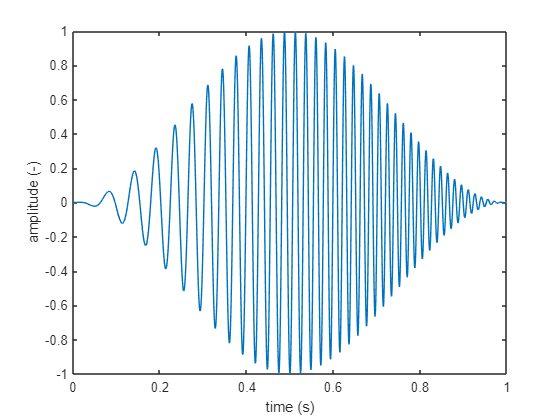

%% Task 1
fs = 2000; % sampling frequency
N = 2000; % number of samples
s = 2000;
y = zeros(s,1);
tp = (0:N-1)/fs; % time range
f1 = 10; %frequency one
f2 = 70; %frequency two
yp = chirp(tp,f1,tp(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
figure()
plot(tp,y2)
xlabel('time (s)')
ylabel('amplitude (-)')

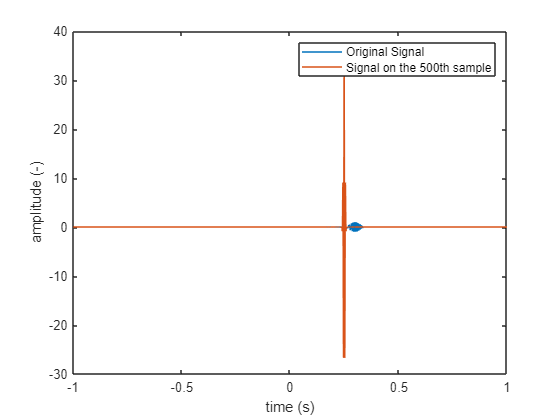

%Ex. 1.1
N = 200; % number of samples
s = 2000;
tp2 = (0:N-1)/fs; % time range
f1 = 10; %frequency one
f2 = 300; %frequency two
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
[yc,lag] = xcorr(y,y2);
tc = lag/fs;
figure()
plot(tp,y)
hold on
plot(tc,yc)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Original Signal','Signal on the 500th sample')

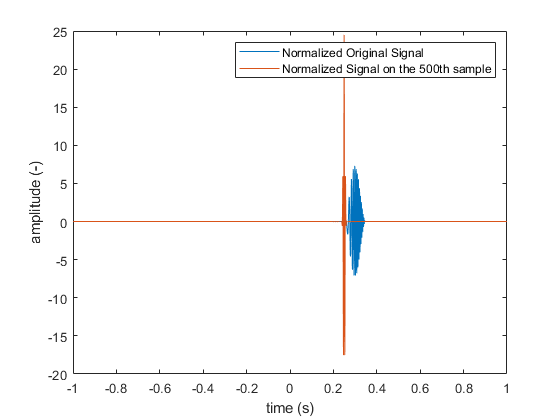

%Normalizing
n = normalize(y);
n2 = normalize(yc);
figure()
plot(tp,n)
hold on
plot(tc,n2)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original Signal','Normalized Signal on the 500th sample')

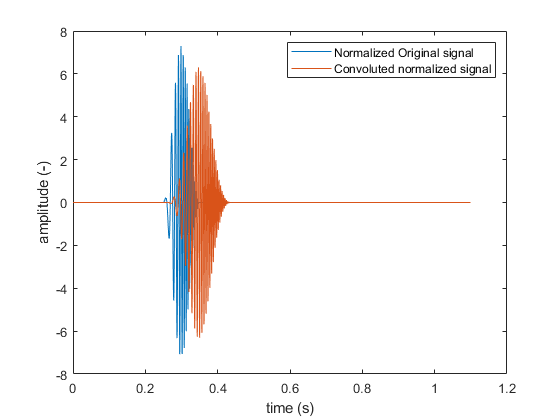

%Trying with convolution
N = 200; % number of samples
s = 200;
tp2 = (0:N-1)/fs; % time range
f1 = 10; %frequency one
f2 = 300; %frequency two
s = 2000;
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
h = conv(y,y2);
t_conv = ((0:length(h)-1)/fs);
n3 = normalize(h);
figure()
plot(tp,n)
hold on
plot(t_conv,n3)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original signal','Convoluted normalized signal')

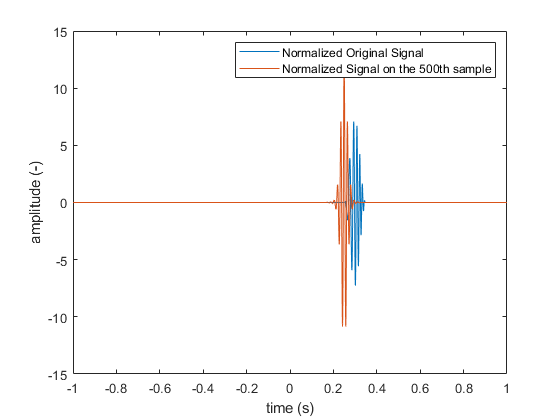

%Ex. 1.2
%f2=100
N = 200; % number of samples
s = 2000;
tp2 = (0:N-1)/fs; % time range
f1 = 30; %frequency one
f2 = 100; %frequency two
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
[yc,lag] = xcorr(y,y2);
tc = lag/fs;
%Normalizing
n = normalize(y);
n2 = normalize(yc);
figure()
plot(tp,n)
hold on
plot(tc,n2)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original Signal','Normalized Signal on the 500th sample')

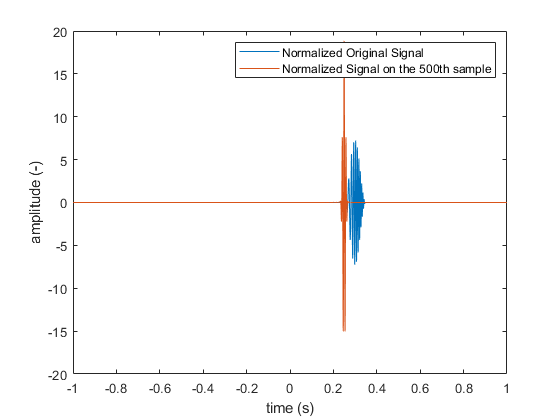

%f2=200
N = 200; % number of samples
s = 2000;
tp2 = (0:N-1)/fs; % time range
f1 = 30; %frequency one
f2 = 200; %frequency two
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
[yc,lag] = xcorr(y,y2);
tc = lag/fs;
%Normalizing
n = normalize(y);
n2 = normalize(yc);
figure()
plot(tp,n)
hold on
plot(tc,n2)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original Signal','Normalized Signal on the 500th sample')

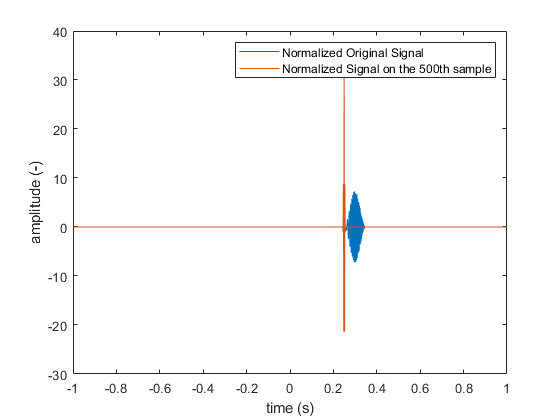

%f2=500
N = 200; % number of samples
s = 2000;
tp2 = (0:N-1)/fs; % time range
f1 = 30; %frequency one
f2 = 500; %frequency two
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
[yc,lag] = xcorr(y,y2);
tc = lag/fs;
%Normalizing
n = normalize(y);
n2 = normalize(yc);
figure()
plot(tp,n)
hold on
plot(tc,n2)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original Signal','Normalized Signal on the 500th sample')

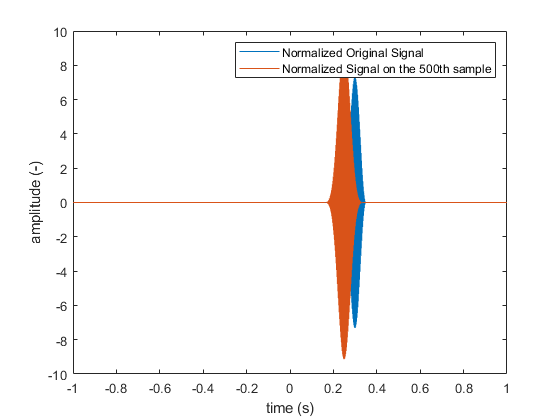

%f1=500 and f2=500
N = 200; % number of samples
s = 2000;
tp2 = (0:N-1)/fs; % time range
f1 = 500; %frequency one
f2 = 500; %frequency two
y = zeros(s,1);
yp = chirp(tp2,f1,tp2(end),f2);
% Creating the Hann windowed signal
y2 = yp.*hann(N)';
y(500:500+length(y2)-1) = y2;
[yc,lag] = xcorr(y,y2);
tc = lag/fs;
%Normalizing
n = normalize(y);
n2 = normalize(yc);
figure()
plot(tp,n)
hold on
plot(tc,n2)
xlabel('time (s)')
ylabel('amplitude (-)')
hold off 
legend('Normalized Original Signal','Normalized Signal on the 500th sample')

Task2